function [Instrument, Node, udpPortArray, udpPortIndex, Localhost_publicIP] = Connection_Instrument(instrList, Timeout, instrInfo, udpPortArray, ConnectionType, ResetCommand, SyncType)

    Type     = instrList.Type{1};
    IP       = instrList.IP{1};
    Port     = str2double(instrList.Port{1});
    inBuffer = instrList.inBuffer(1);
    
    udpPortIndex       = [];
    Localhost_publicIP = '';
    
    instrreset
    pause(1)

    if strcmp(Type, 'Visa TCPIP'); Instrument = visa('ni', ['TCPIP0::' IP '::inst0::INSTR']); 
    else;                          Instrument = tcpip(IP, Port);
    end
    
    set(Instrument, 'Timeout', Timeout, 'InputBufferSize', inBuffer*1e+6, 'ByteOrder', 'littleEndian');
    fopen(Instrument);
    
    Node = Misc_Hostname(Instrument);
    
    if contains(ConnectionType, 'Task')
        instrInd = find(strcmp(instrInfo.Name, instrList.Name{1}), 1);

        if strcmp(ResetCommand, 'On')
            fprintf(Instrument, instrInfo.scpiReset{instrInd});
            pause(instrInfo.ResetPause{instrInd})
        end
        
        fprintf(Instrument, instrInfo.StartUp{instrInd});
        
        switch SyncType
            case 'Single Sweep';     fprintf(Instrument, 'INITiate:CONTinuous OFF');
            case 'Continuous Sweep'; fprintf(Instrument, 'INITiate:CONTinuous ON');
        end

        switch instrInfo.connectFlag{instrInd}
            case 1
                % Analisadores de espectro
                
            case 2
                % EB500
                if ~isempty(instrList.Localhost_localIP{1})
                    Localhost_localIP = instrList.Localhost_localIP{1};
                    if ~isempty(instrList.Localhost_publicIP); Localhost_publicIP = instrList.Localhost_publicIP{1};
                    else;                                      Localhost_publicIP = Localhost_localIP;
                    end
                else
                    [~, Localhost_publicIP] = Misc_ClientIPs(IP);
                end
                
                [udpPortArray, udpPortIndex] = Connection_udpLogger(udpPortArray, 24001, Timeout);
        end
    end

end

## Função auxiliar 1: Hostname

function Node = Misc_Hostname(Instrument)

    Node = deblank(query(Instrument, '*IDN?'));
    Node = replace(Node, '"', '');

    if isempty(Node)
        error('EmptyName')
    end
    
end

## Função auxiliar 2: Local e public IPs

Conforme apresentada nas imagens abaixo (Windows em diversos idiomas), o *template* da resposta ao comando do sistema "arp -a" possui os caracteres " --- " nas linhas em que constam os endereços de IP do cliente.

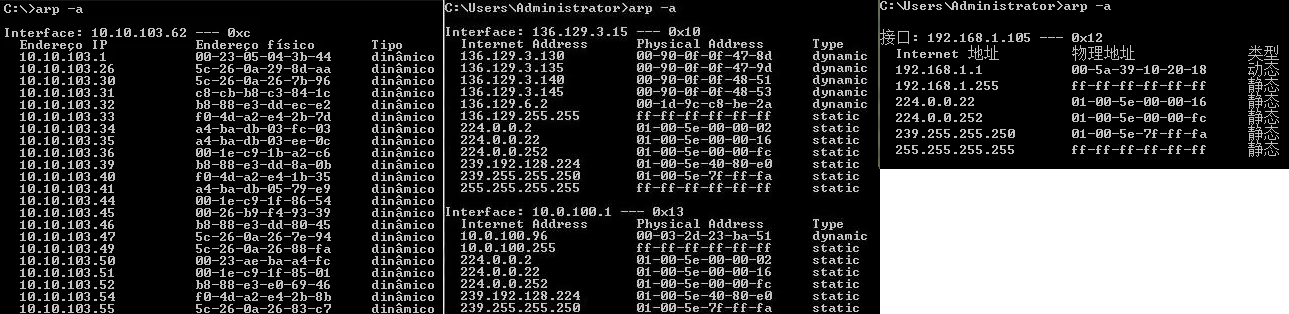

function [localIP, publicIP] = Misc_ClientIPs(instrIP)

    [~, msg] = system('arp -a');

    msgCell  = strsplit(msg, newline)';
    
    indEmpty = cellfun(@(x) isempty(x), msgCell);
    msgCell(indEmpty) = [];
    
    ind_localIPs = find(cellfun(@(x) contains(x, ' --- '), msgCell));
    ind_instrIPs = find(cellfun(@(x) contains(x, [' ' instrIP ' ']), msgCell));
    
    localIP = '';
    if ~isempty(ind_instrIPs)
        ind_instrIPs = ind_instrIPs(1);
        
        temp = ind_localIPs - ind_instrIPs;
        ind  = find(temp<0);
        ind  = ind(end);
                
        localIP  = char(regexp(msgCell{ind_localIPs(ind)}, '(\d{1,3}.\d{1,3}.\d{1,3}.\d{1,3})', 'match'));
        publicIP = localIP;
        
    else
        localIPs = {};
        for ii = 1:numel(ind_localIPs)
            localIPs = [localIPs, regexp(msgCell{ind_localIPs(ii)}, '(\d{1,3}.\d{1,3}.\d{1,3}.\d{1,3})', 'match')];
        end
        
        for jj = 1:numel(localIPs)
            if ~system(sprintf('ping -n 3 -w 1000 -S %s %s', localIPs{jj}, instrIP))
                localIP = localIPs{jj};
                break
            end
        end
        
        publicIP = char(regexp(webread('http://checkip.dyndns.org'), '(\d{1,3}.\d{1,3}.\d{1,3}.\d{1,3})', 'match'));
    end

end